load("lattice_calibration_data/15x15x15/trial4/lattice_data_1");
load("lattice_calibration_data/15x15x15/characteristic_2.mat");

fz_estimated = estimate_lattice_force(z,t_biased,t_inv,k,r(1),r(2),kr);

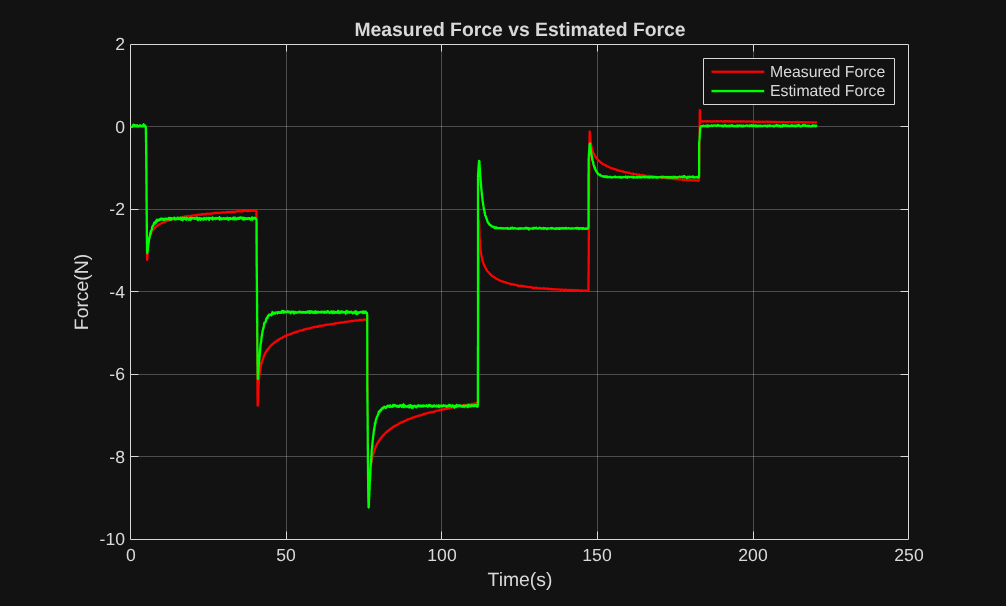

figure;
plot(t_biased,fz,"LineWidth",1.3,"Color","red");
hold on;
plot(t_biased,fz_estimated,"LineWidth",1.3,"Color","green");
grid on;
xlabel("Time(s)");
ylabel("Force(N)");
legend(["Measured Force","Estimated Force"]);
title("Measured Force vs Estimated Force");

hold off;

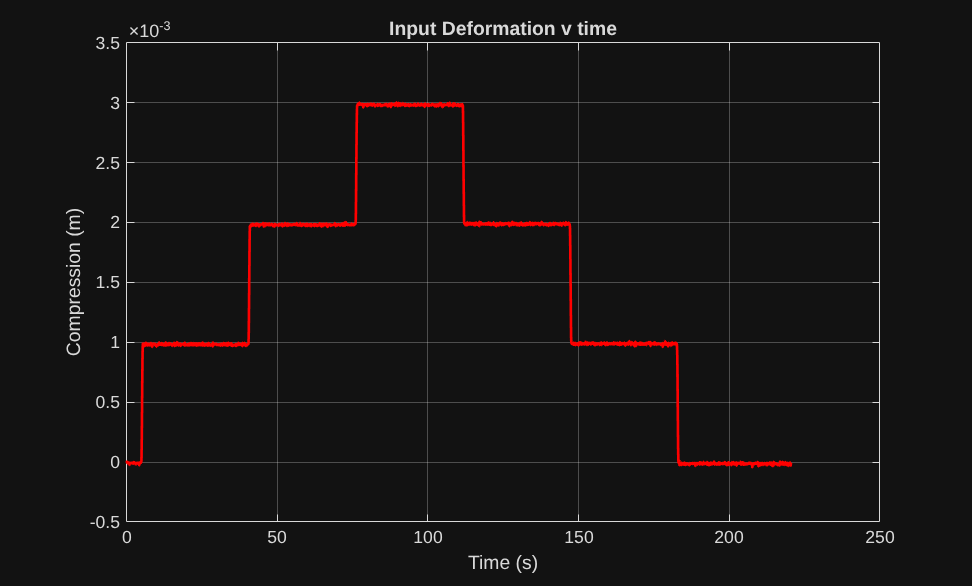

figure;
plot(t_biased,z,"LineWidth",1.5,"Color","red");
hold on;
title("Input Deformation v time");
xlabel("Time (s)");
ylabel("Compression (m)");
grid on;
hold off